讀取影像

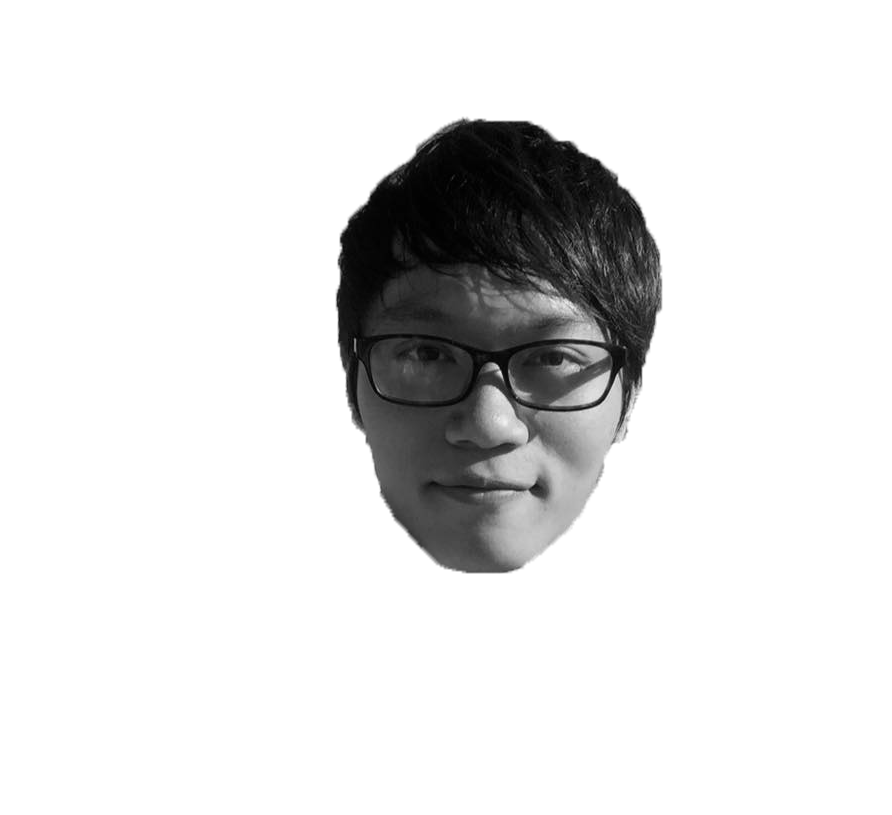

I1 = imread('W1.bmp');
G1 = rgb2gray(I1);
imshow(G1)

旋轉影像

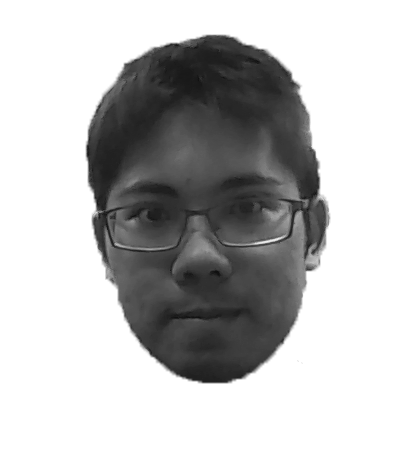

I2 = imread('T1.bmp');%G2 = imresize(imrotate(G1,-20),1.2);
G2 = rgb2gray(I2);
imshow(G2)

尋找SURF特徵

points1 = detectSURFFeatures(G1);
points2 = detectSURFFeatures(G2);

顯示特徵點

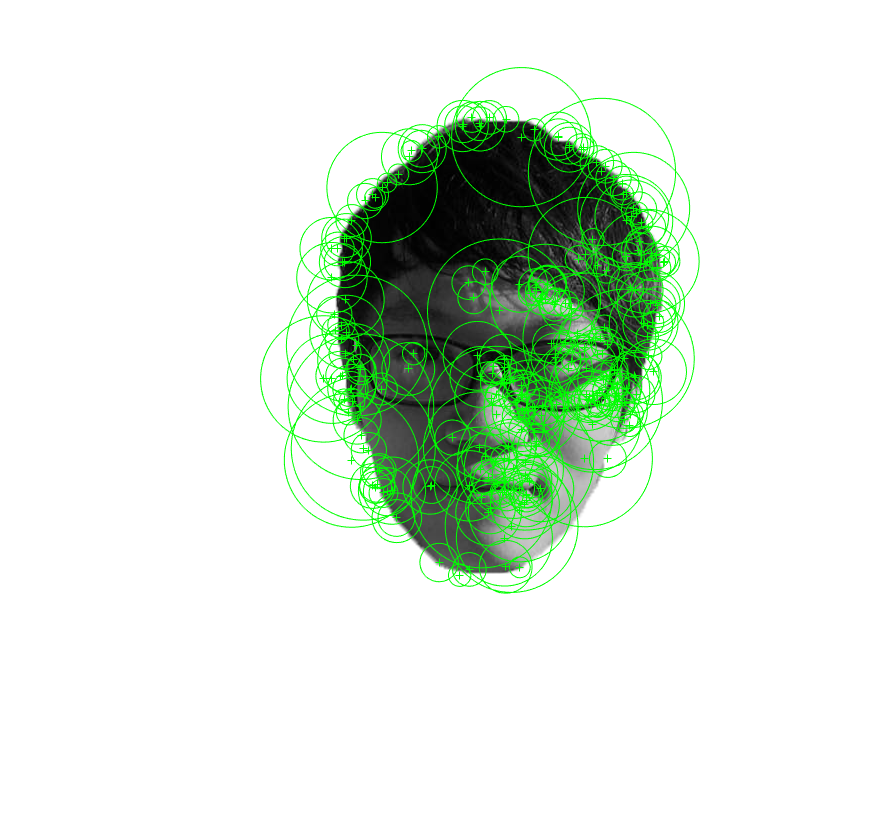

imshow(G1); hold on;
plot(points1.selectStrongest(1000));

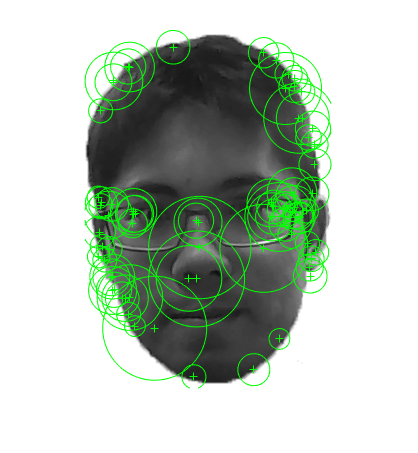

figure;
imshow(G2); hold on;
plot(points2.selectStrongest(1000));

提取特徵

[f1,vpts1] = extractFeatures(G1,points1);
[f2,vpts2] = extractFeatures(G2,points2);

檢索匹配點的位置

indexPairs = matchFeatures(f1,f2) ;
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));

顯示配對點

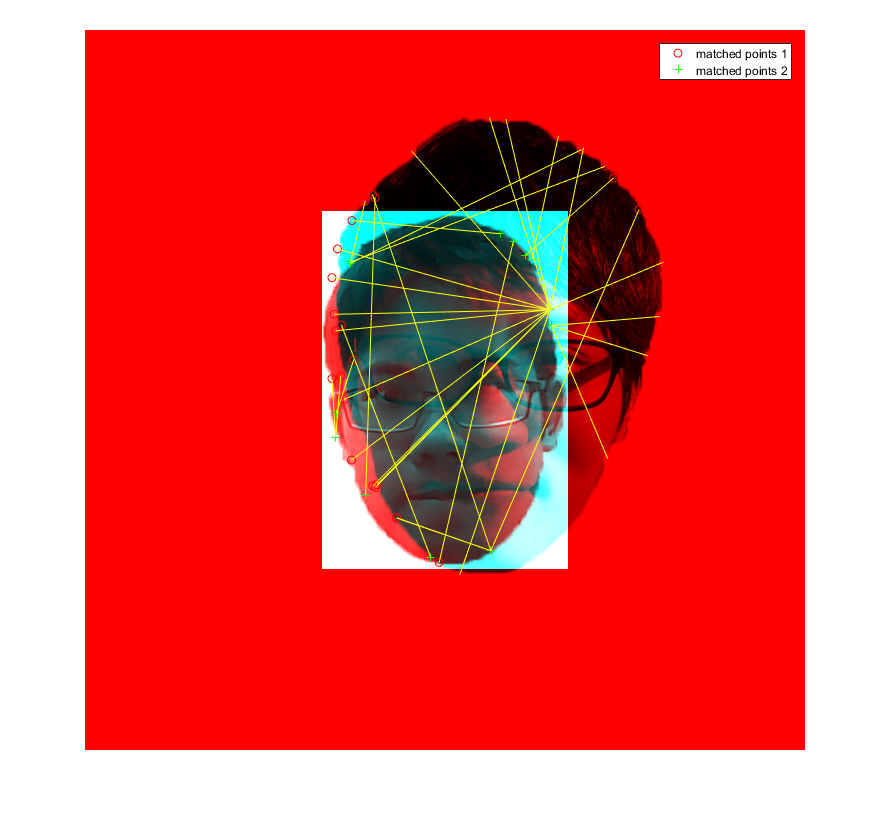

figure; showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2);
legend('matched points 1','matched points 2');